# Classification of Hyperspectral Images

## Exercise 3, Part 0: Prerequisite - load input data

data = helper.loadData();
vizData = data.vizData;
featData = data.featData;

## Exercise 3, Part 1: Load and visualize single fruit hyperspectral data

Specify fruit number (1 to 4)

fruitNumber =1;

Specify slice number (1 to 249)

sliceNumber = 176;

Read in specified fruit and display it. Scroll through to visualize 2-D slides of the data over all wavelengths. 

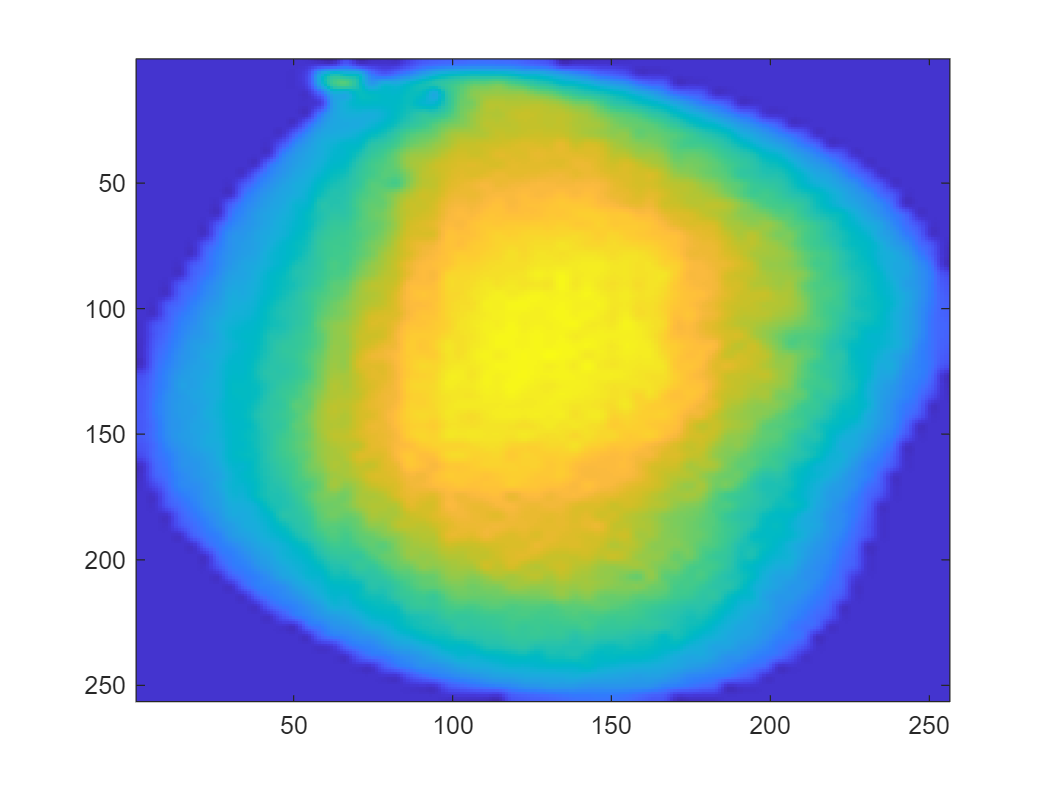

day = 1;
hyperCubeStruct = helper.loadFruit(vizData, fruitNumber, day);
hDataCube = hyperCubeStruct.DataCube;

imagesc(imresize(hDataCube(:,:,sliceNumber), [256 256]));

## Exercise 3, Part 2: Visualize falsified color image

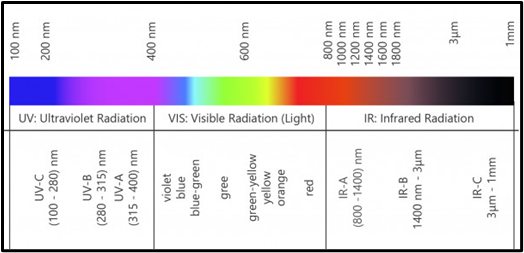 [2]

The dataset contains images captured from wavelengths approximately between 400nm and 900nm, which spans the visible and infrared spectrum range. It is easier to inspect the data by adding false color to the data. The color may not be representative of the original color of the data but helps you understand specific things that you may want to notice. 

Pick three bands of your choice from the drop-down to generate falsified color images and notice how the results change! 

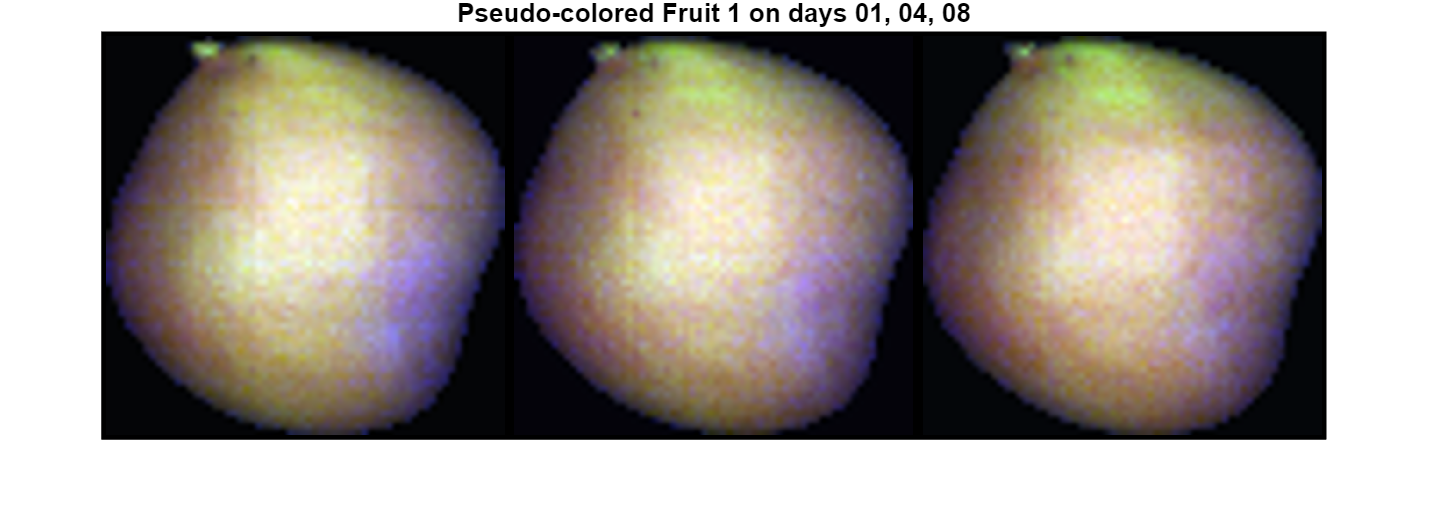

Band1 =  "IR"; %Infrared
Band2 =  "red"; %red
Band3 =  "violet"; %violet

bands = [Band1, Band2, Band3];
helper.visualizeFalseColoredFruit(vizData, fruitNumber, bands);

## Exercise 3, Part 3: Visualize extracted features from hyperspectral data

Feature extraction refers to extracting useful information from data through transformation of its numerical contents while preserving information in the original data.

Here, mean of every 2-D slice is calculated thereby generating one value per wavelength range. Observe how plot varies for every day for each fruit. Is there substantial difference? These are the differences that the machine learning classifier will later pick up to learn patterns about each day of the fruit. 

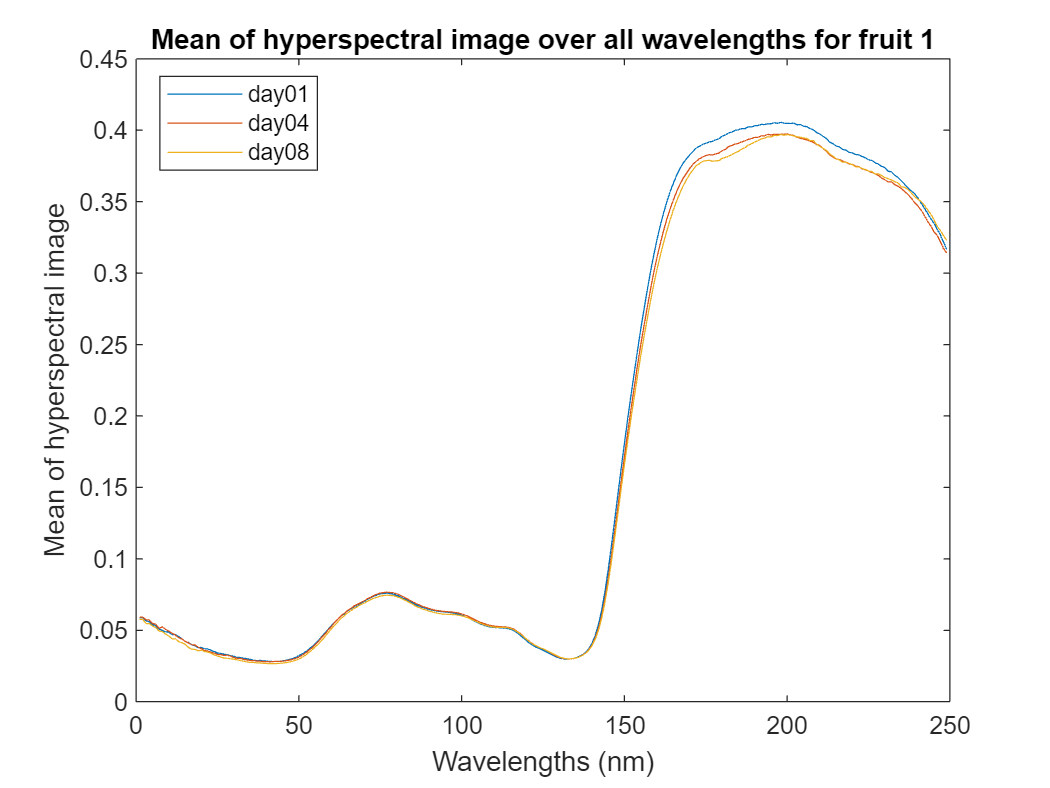

helper.visualizeFeaturesFruit(featData, fruitNumber)

## Exercise 3, Part 4a: Train machine learning classifier

You will use the features displayed in the previous section to train a machine learning classififer to learn the age of the fruit. The machine learning classifier used here is a discriminant classifier which used statistical patterns in the data to look for differences in each group of the data and learn it to classify. 

Specify any 5 fruit numbers between 1-40 to hold out for testing

testFruits = [1, 14, 20, 28, 30, 40];

Split the dataset into train and test dataset

dataTest = featData(contains(featData.FruitNumber, string(testFruits)),:);
dataTrain = featData(~contains(featData.FruitNumber, string(testFruits)),:);

Train classifier using train data

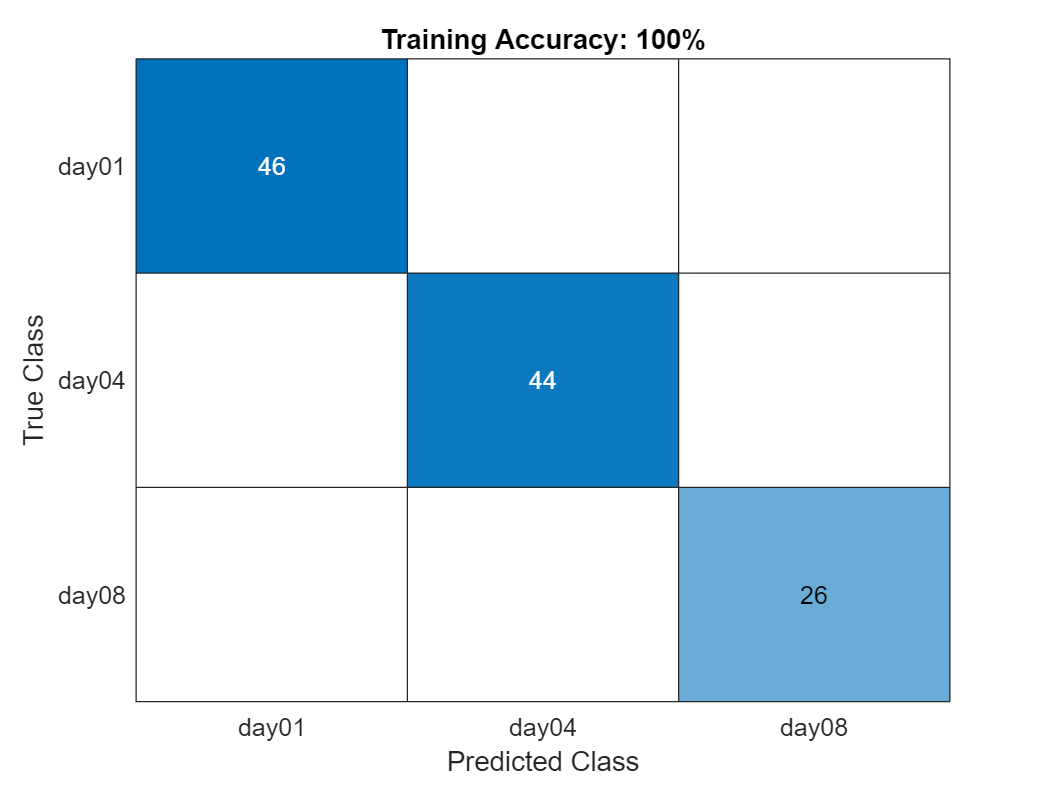

[trainedClassifier, validationAccuracy] = helper.trainClassifier(dataTrain);

## Exercise 3, Part 4b: Run inference on a test (new) fruit

To test if the classifier works well, we run it through a fruit that the model hasn't seen while training. Ideally, the model should extend its learnings on the training data to unseen data and perform in a similar way to training data. Observe if the training accuracy from previous section extends when you run the model through unseen data. 

Specify one of the fruit numbers from test fruits listed on the previous section (line 18)

fruitNumber = 1;

Run test fruit through model and display results. Notice if the true labels match with the predicted labels. 

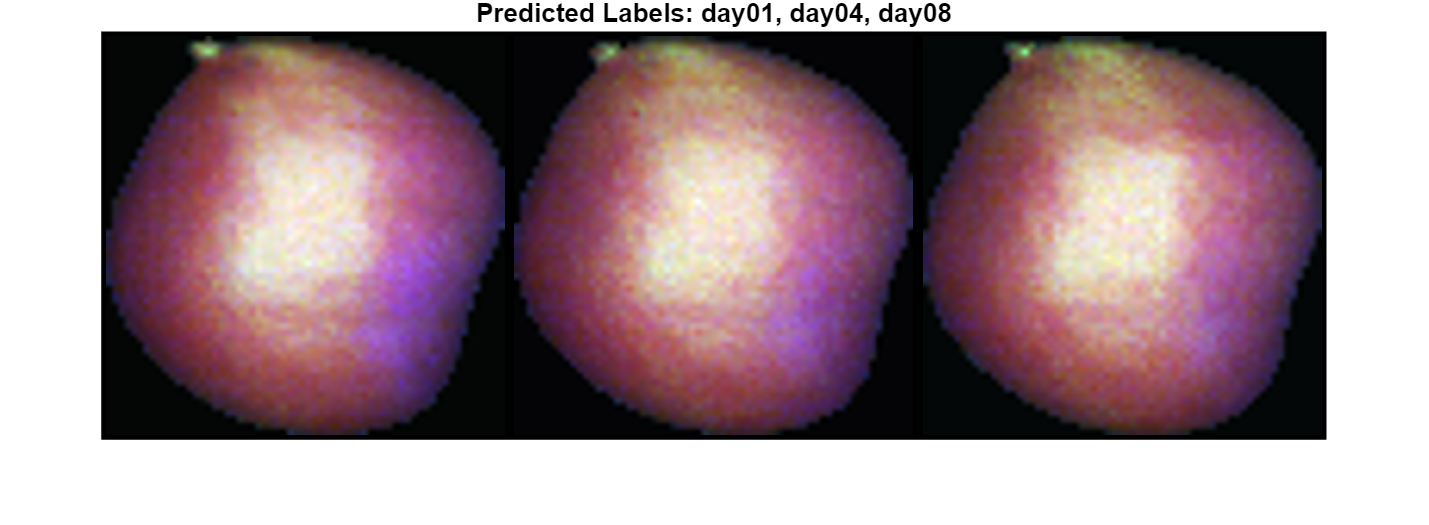

% Extract indices of selected fruit over all days
fruitRowIdx = find(featData.FruitNumber == sprintf("%02d", fruitNumber) & ...
    featData.FruitDirection == "front");

% Run prediction
predLabels = trainedClassifier.predictFcn(featData(fruitRowIdx,:));

% Plot prediction results 
helper.visualizeFalseColoredFruit(vizData, fruitNumber, bands);
[t,s] = title("Pseudo-colored Fruit " + fruitNumber + " on days " + ...
    join(extractAfter(string(featData.Response(fruitRowIdx)), "day"), ", ") + newline + ...
    "Predicted Labels: " + join(predLabels, ", "));

## **References:**

[1] Varga, Leon Amadeus, Jan Makowski, and Andreas Zell. "Measuring the ripeness of fruit with hyperspectral imaging and deep learning." *2021 International Joint Conference on Neural Networks (IJCNN)*. IEEE, 2021.�

[2]. [https://www.gigahertz-optik.com/en-us/service-and-support/knowledge-base/basics-light-measurement/light-color/opt-rad-wavelength-range/](https://www.gigahertz-optik.com/en-us/service-and-support/knowledge-base/basics-light-measurement/light-color/opt-rad-wavelength-range/) as of Sep 12, 2023. 